# 空間相関Plotの作成

## ①beforeFit　②afterFit　③overlay (beforeFitとafterFit) 

folder_name_output = sprintf("output/%s/%s", DATE, sample_name);

folder_name_output = "output/221209/20nm"

if not(exist(folder_name_output,'dir'))
    mkdir(folder_name_output)
end

### ①beforeFit

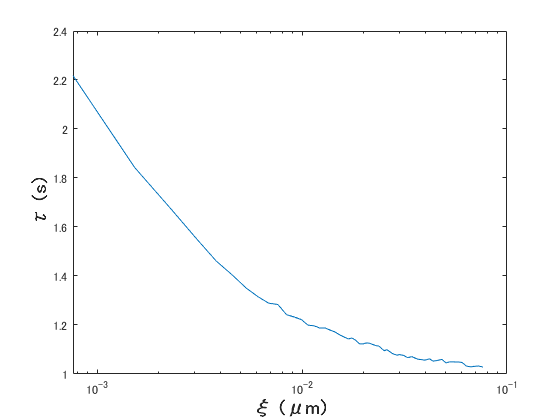

%plot
figure
semilogx(TAU,COR)
xlabel('ξ (μm)','FontSize',14,'FontWeight','bold');
ylabel('τ (s)','FontSize',14,'FontWeight','bold');

### ②afterFit

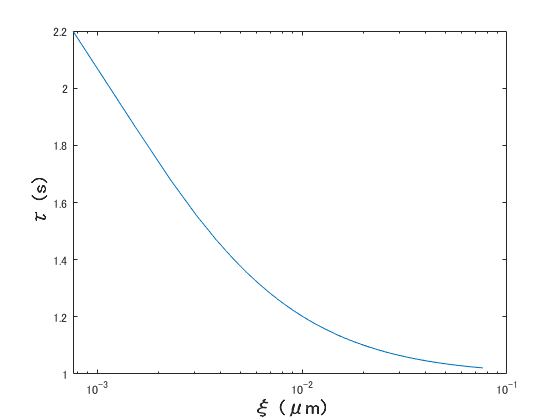

%plot
figure
semilogx(TAU, modelfun_3dim_temporal(parms,TAU))
xlabel('ξ (μm)','FontSize',14,'FontWeight','bold');
ylabel('τ (s)','FontSize',14,'FontWeight','bold');

### ③overlay

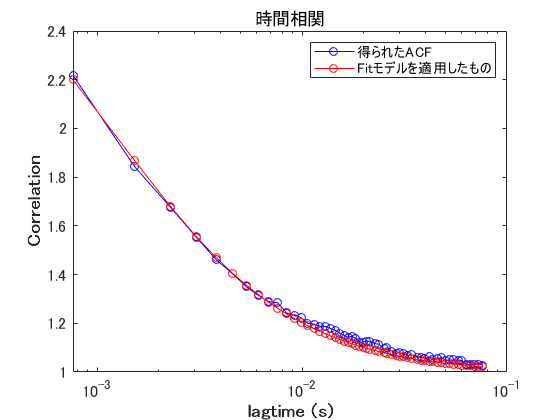

%plot
semilogx(TAU,COR, "b-o")
ax = gca; % current axes
ax.FontSize = 12;
xlabel("lagtime (s)", 'FontSize',14,'FontWeight','bold');
ylabel("Correlation", 'FontSize',14,'FontWeight','bold');

hold on;

semilogx(TAU, modelfun_3dim_temporal(parms,TAU), "r-o")
legend("得られたACF","Fitモデルを適用したもの", 'Location','northeast');

hold off;

%save figure
figurename = erase(filename, ".lsm");
title(sprintf("時間相関 %s", sample_name));
saveas(gcf, sprintf("output/%s/%s/temporal_fitting %s.fig",DATE, sample_name,figurename))

saveas(gcf, sprintf("output/%s/%s/temporal_fitting %s.png",DATE, sample_name,figurename))